%part a
%define angles given
theta2 = 40:5:60;
theta4 = [70, 76, 83, 91, 100];

%get k1 k2 k3
A = []


A =

     []



B = []


B =

     []



for i = 1:length(theta2)
    temp1 = [(cosd(theta4(i))) (-1 * (cosd(theta2(i)))) (1)];
    temp2 = cosd(theta2(i)-theta4(i));
    A = [A; temp1];
    B = [B; temp2];
end
%link_ratios = lsqr(A,B); alternative solution
sol = linsolve(A,B);
k1 = sol(1,1)

k1 = 1.0201

k2 = sol(2,1)

k2 = 1.6053

k3 = sol(3,1)

k3 = 1.7464

%get link lengths
d = 180;
a = abs(d/k1);
c = abs(d/k2);
b = abs(sqrt(a * a + c * c + d * d - 2 * a * c * k3));
fprintf("a %d b %d c %d", a,b,c)

a 1.764601e+02 b 8.367472e+01 c 1.121312e+02

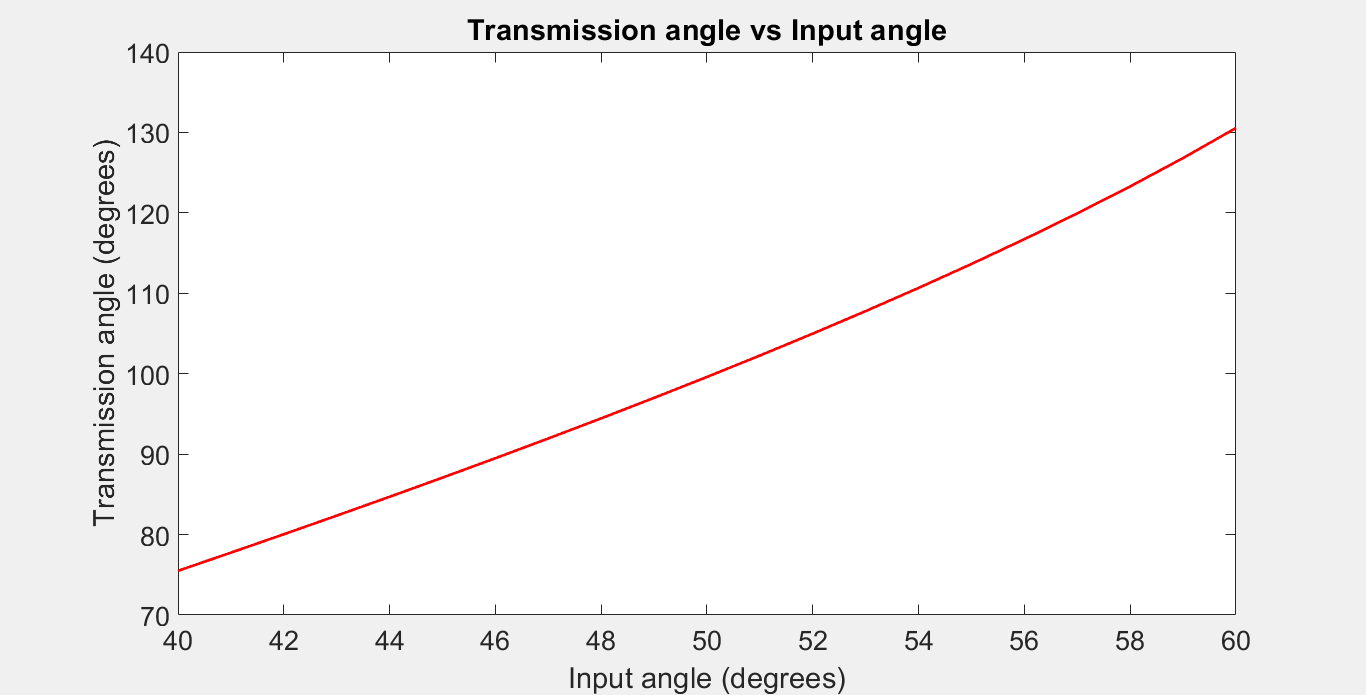

%part b
% transmission angle
inputAngle = 40:1:60;
transAngle = acosd((b*b + c*c - (a*a+d*d) + 2 * a * d * cosd(inputAngle))/ (2 * b * c));
plot(inputAngle, transAngle, 'r', 'LineWidth',2)
figure(1)
title('Transmission angle vs Input angle')
xlabel('Input angle (degrees)')
ylabel('Transmission angle (degrees)')
set(gcf,'Position', get(0,'Screensize'));
set(gcf,'Visible','on')
set(gca, 'FontSize', 20)

%part c
%relationship of theta2 to theta4
theta2C = 40:1:60

theta2C =     40    41    42    43    44    45    46    47    48    49    50    51    52    53    54    55    56    57    58    59    60


theta4CN = zeros(1,21)

theta4CN =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


theta4CP = zeros(1,21)

theta4CP =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for j = 1:21
    Ar = sind(theta2C(j))
    Br = cosd(theta2C(j)) - k1
    Cr = k3 - k2 * cosd(theta2C(j))
    theta4CN(j) = 2 * atand((Ar - sqrt(Ar.^2 + Br.^2 - Cr.^2))/(Br+Cr))
    theta4CP(j) = 2 * atand((Ar + sqrt(Ar.^2 + Br.^2 - Cr.^2))/(Br+Cr))
end

Ar = 0.6428

Br = -0.2540

Cr = 0.5167

theta4CN =    69.9417         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


theta4CP =   153.1841         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Ar = 0.6561

Br = -0.2654

Cr = 0.5349

theta4CN =    69.9417   71.1169         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


theta4CP =   153.1841  152.9260         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Ar = 0.6691

Br = -0.2769

Cr = 0.5534

theta4CN =    69.9417   71.1169   72.3213         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


theta4CP =   153.1841  152.9260  152.6426         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Ar = 0.6820

Br = -0.2887

Cr = 0.5724

theta4CN =    69.9417   71.1169   72.3213   73.5546         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


theta4CP =   153.1841  152.9260  152.6426  152.3336         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Ar = 0.6947

Br = -0.3007

Cr = 0.5917

theta4CN =    69.9417   71.1169   72.3213   73.5546   74.8169         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


theta4CP =   153.1841  152.9260  152.6426  152.3336  151.9991         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Ar = 0.7071

Br = -0.3130

Cr = 0.6113

theta4CN =    69.9417   71.1169   72.3213   73.5546   74.8169   76.1082         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


theta4CP =   153.1841  152.9260  152.6426  152.3336  151.9991  151.6386         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Ar = 0.7193

Br = -0.3254

Cr = 0.6313

theta4CN =    69.9417   71.1169   72.3213   73.5546   74.8169   76.1082   77.4289         0         0         0         0         0         0         0         0         0         0         0         0         0         0


theta4CP =   153.1841  152.9260  152.6426  152.3336  151.9991  151.6386  151.2515         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Ar = 0.7314

Br = -0.3381

Cr = 0.6516

theta4CN =    69.9417   71.1169   72.3213   73.5546   74.8169   76.1082   77.4289   78.7796         0         0         0         0         0         0         0         0         0         0         0         0         0


theta4CP =   153.1841  152.9260  152.6426  152.3336  151.9991  151.6386  151.2515  150.8371         0         0         0         0         0         0         0         0         0         0         0         0         0


Ar = 0.7431

Br = -0.3509

Cr = 0.6722

theta4CN =    69.9417   71.1169   72.3213   73.5546   74.8169   76.1082   77.4289   78.7796   80.1612         0         0         0         0         0         0         0         0         0         0         0         0


theta4CP =   153.1841  152.9260  152.6426  152.3336  151.9991  151.6386  151.2515  150.8371  150.3943         0         0         0         0         0         0         0         0         0         0         0         0


Ar = 0.7547

Br = -0.3640

Cr = 0.6932

theta4CN =    69.9417   71.1169   72.3213   73.5546   74.8169   76.1082   77.4289   78.7796   80.1612   81.5749         0         0         0         0         0         0         0         0         0         0         0


theta4CP =   153.1841  152.9260  152.6426  152.3336  151.9991  151.6386  151.2515  150.8371  150.3943  149.9218         0         0         0         0         0         0         0         0         0         0         0


Ar = 0.7660

Br = -0.3773

Cr = 0.7145

theta4CN =    69.9417   71.1169   72.3213   73.5546   74.8169   76.1082   77.4289   78.7796   80.1612   81.5749   83.0221         0         0         0         0         0         0         0         0         0         0


theta4CP =   153.1841  152.9260  152.6426  152.3336  151.9991  151.6386  151.2515  150.8371  150.3943  149.9218  149.4179         0         0         0         0         0         0         0         0         0         0


Ar = 0.7771

Br = -0.3907

Cr = 0.7362

theta4CN =    69.9417   71.1169   72.3213   73.5546   74.8169   76.1082   77.4289   78.7796   80.1612   81.5749   83.0221   84.5047         0         0         0         0         0         0         0         0         0


theta4CP =   153.1841  152.9260  152.6426  152.3336  151.9991  151.6386  151.2515  150.8371  150.3943  149.9218  149.4179  148.8808         0         0         0         0         0         0         0         0         0


Ar = 0.7880

Br = -0.4044

Cr = 0.7581

theta4CN =    69.9417   71.1169   72.3213   73.5546   74.8169   76.1082   77.4289   78.7796   80.1612   81.5749   83.0221   84.5047   86.0250         0         0         0         0         0         0         0         0


theta4CP =   153.1841  152.9260  152.6426  152.3336  151.9991  151.6386  151.2515  150.8371  150.3943  149.9218  149.4179  148.8808  148.3079         0         0         0         0         0         0         0         0


Ar = 0.7986

Br = -0.4182

Cr = 0.7803

theta4CN =    69.9417   71.1169   72.3213   73.5546   74.8169   76.1082   77.4289   78.7796   80.1612   81.5749   83.0221   84.5047   86.0250   87.5858         0         0         0         0         0         0         0


theta4CP =   153.1841  152.9260  152.6426  152.3336  151.9991  151.6386  151.2515  150.8371  150.3943  149.9218  149.4179  148.8808  148.3079  147.6963         0         0         0         0         0         0         0


Ar = 0.8090

Br = -0.4323

Cr = 0.8028

theta4CN =    69.9417   71.1169   72.3213   73.5546   74.8169   76.1082   77.4289   78.7796   80.1612   81.5749   83.0221   84.5047   86.0250   87.5858   89.1906         0         0         0         0         0         0


theta4CP =   153.1841  152.9260  152.6426  152.3336  151.9991  151.6386  151.2515  150.8371  150.3943  149.9218  149.4179  148.8808  148.3079  147.6963  147.0425         0         0         0         0         0         0


Ar = 0.8192

Br = -0.4465

Cr = 0.8256

theta4CN =    69.9417   71.1169   72.3213   73.5546   74.8169   76.1082   77.4289   78.7796   80.1612   81.5749   83.0221   84.5047   86.0250   87.5858   89.1906   90.8439         0         0         0         0         0


theta4CP =   153.1841  152.9260  152.6426  152.3336  151.9991  151.6386  151.2515  150.8371  150.3943  149.9218  149.4179  148.8808  148.3079  147.6963  147.0425  146.3419         0         0         0         0         0


Ar = 0.8290

Br = -0.4609

Cr = 0.8487

theta4CN =    69.9417   71.1169   72.3213   73.5546   74.8169   76.1082   77.4289   78.7796   80.1612   81.5749   83.0221   84.5047   86.0250   87.5858   89.1906   90.8439   92.5509         0         0         0         0


theta4CP =   153.1841  152.9260  152.6426  152.3336  151.9991  151.6386  151.2515  150.8371  150.3943  149.9218  149.4179  148.8808  148.3079  147.6963  147.0425  146.3419  145.5890         0         0         0         0


Ar = 0.8387

Br = -0.4754

Cr = 0.8721

theta4CN =    69.9417   71.1169   72.3213   73.5546   74.8169   76.1082   77.4289   78.7796   80.1612   81.5749   83.0221   84.5047   86.0250   87.5858   89.1906   90.8439   92.5509   94.3188         0         0         0


theta4CP =   153.1841  152.9260  152.6426  152.3336  151.9991  151.6386  151.2515  150.8371  150.3943  149.9218  149.4179  148.8808  148.3079  147.6963  147.0425  146.3419  145.5890  144.7769         0         0         0


Ar = 0.8480

Br = -0.4901

Cr = 0.8957

theta4CN =    69.9417   71.1169   72.3213   73.5546   74.8169   76.1082   77.4289   78.7796   80.1612   81.5749   83.0221   84.5047   86.0250   87.5858   89.1906   90.8439   92.5509   94.3188   96.1562         0         0


theta4CP =   153.1841  152.9260  152.6426  152.3336  151.9991  151.6386  151.2515  150.8371  150.3943  149.9218  149.4179  148.8808  148.3079  147.6963  147.0425  146.3419  145.5890  144.7769  143.8965         0         0


Ar = 0.8572

Br = -0.5050

Cr = 0.9196

theta4CN =    69.9417   71.1169   72.3213   73.5546   74.8169   76.1082   77.4289   78.7796   80.1612   81.5749   83.0221   84.5047   86.0250   87.5858   89.1906   90.8439   92.5509   94.3188   96.1562   98.0750         0


theta4CP =   153.1841  152.9260  152.6426  152.3336  151.9991  151.6386  151.2515  150.8371  150.3943  149.9218  149.4179  148.8808  148.3079  147.6963  147.0425  146.3419  145.5890  144.7769  143.8965  142.9362         0


Ar = 0.8660

Br = -0.5201

Cr = 0.9437

theta4CN =    69.9417   71.1169   72.3213   73.5546   74.8169   76.1082   77.4289   78.7796   80.1612   81.5749   83.0221   84.5047   86.0250   87.5858   89.1906   90.8439   92.5509   94.3188   96.1562   98.0750  100.0908


theta4CP =   153.1841  152.9260  152.6426  152.3336  151.9991  151.6386  151.2515  150.8371  150.3943  149.9218  149.4179  148.8808  148.3079  147.6963  147.0425  146.3419  145.5890  144.7769  143.8965  142.9362  141.8800


sError = zeros(1,21)

sError =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


sError2 = zeros(1,21)

sError2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


%get structural errors
for j = 1:length(theta2C)
    sError(j) = k1 * cosd(theta4CP(j)) - k2 * cosd(theta2C(j)) + k3 - cosd(theta2C(j) - theta4CP(j))
    sError2(j) = k1 * cosd(theta4CN(j)) - k2 * cosd(theta2C(j)) + k3 - cosd(theta2C(j) - theta4CN(j))
end

sError = 	1.0e+-15 *

   -0.4441         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


sError2 = 	1.0e+-15 *

   -0.2220         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


sError = 	1.0e+-15 *

   -0.4441   -0.1110         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


sError2 = 	1.0e+-15 *

   -0.2220   -0.1110         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


sError =    -0.4441   -0.1110   -0.0555         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


sError2 =    -0.2220   -0.1110    0.1110         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


sError =    -0.4441   -0.1110   -0.0555   -0.2776         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


sError2 =    -0.2220   -0.1110    0.1110   -0.1110         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


sError =    -0.4441   -0.1110   -0.0555   -0.2776   -0.2776         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


sError2 =    -0.2220   -0.1110    0.1110   -0.1110   -0.1110         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


sError =    -0.4441   -0.1110   -0.0555   -0.2776   -0.2776   -0.2220         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


sError2 =    -0.2220   -0.1110    0.1110   -0.1110   -0.1110   -0.2220         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


sError =    -0.4441   -0.1110   -0.0555   -0.2776   -0.2776   -0.2220    0.1665         0         0         0         0         0         0         0         0         0         0         0         0         0         0


sError2 =    -0.2220   -0.1110    0.1110   -0.1110   -0.1110   -0.2220    0.1110         0         0         0         0         0         0         0         0         0         0         0         0         0         0


sError =    -0.4441   -0.1110   -0.0555   -0.2776   -0.2776   -0.2220    0.1665    0.1388         0         0         0         0         0         0         0         0         0         0         0         0         0


sError2 =    -0.2220   -0.1110    0.1110   -0.1110   -0.1110   -0.2220    0.1110    0.2220         0         0         0         0         0         0         0         0         0         0         0         0         0


sError =    -0.4441   -0.1110   -0.0555   -0.2776   -0.2776   -0.2220    0.1665    0.1388   -0.1388         0         0         0         0         0         0         0         0         0         0         0         0


sError2 =    -0.2220   -0.1110    0.1110   -0.1110   -0.1110   -0.2220    0.1110    0.2220    0.1110         0         0         0         0         0         0         0         0         0         0         0         0


sError =    -0.4441   -0.1110   -0.0555   -0.2776   -0.2776   -0.2220    0.1665    0.1388   -0.1388         0         0         0         0         0         0         0         0         0         0         0         0


sError2 =    -0.2220   -0.1110    0.1110   -0.1110   -0.1110   -0.2220    0.1110    0.2220    0.1110   -0.1110         0         0         0         0         0         0         0         0         0         0         0


sError =    -0.4441   -0.1110   -0.0555   -0.2776   -0.2776   -0.2220    0.1665    0.1388   -0.1388         0    0.1110         0         0         0         0         0         0         0         0         0         0


sError2 =    -0.2220   -0.1110    0.1110   -0.1110   -0.1110   -0.2220    0.1110    0.2220    0.1110   -0.1110         0         0         0         0         0         0         0         0         0         0         0


sError =    -0.4441   -0.1110   -0.0555   -0.2776   -0.2776   -0.2220    0.1665    0.1388   -0.1388         0    0.1110         0         0         0         0         0         0         0         0         0         0


sError2 =    -0.2220   -0.1110    0.1110   -0.1110   -0.1110   -0.2220    0.1110    0.2220    0.1110   -0.1110         0   -0.1110         0         0         0         0         0         0         0         0         0


sError =    -0.4441   -0.1110   -0.0555   -0.2776   -0.2776   -0.2220    0.1665    0.1388   -0.1388         0    0.1110         0    0.3608         0         0         0         0         0         0         0         0


sError2 =    -0.2220   -0.1110    0.1110   -0.1110   -0.1110   -0.2220    0.1110    0.2220    0.1110   -0.1110         0   -0.1110   -0.1110         0         0         0         0         0         0         0         0


sError =    -0.4441   -0.1110   -0.0555   -0.2776   -0.2776   -0.2220    0.1665    0.1388   -0.1388         0    0.1110         0    0.3608         0         0         0         0         0         0         0         0


sError2 =    -0.2220   -0.1110    0.1110   -0.1110   -0.1110   -0.2220    0.1110    0.2220    0.1110   -0.1110         0   -0.1110   -0.1110   -0.2220         0         0         0         0         0         0         0


sError =    -0.4441   -0.1110   -0.0555   -0.2776   -0.2776   -0.2220    0.1665    0.1388   -0.1388         0    0.1110         0    0.3608         0    0.1527         0         0         0         0         0         0


sError2 =    -0.2220   -0.1110    0.1110   -0.1110   -0.1110   -0.2220    0.1110    0.2220    0.1110   -0.1110         0   -0.1110   -0.1110   -0.2220    0.1110         0         0         0         0         0         0


sError =    -0.4441   -0.1110   -0.0555   -0.2776   -0.2776   -0.2220    0.1665    0.1388   -0.1388         0    0.1110         0    0.3608         0    0.1527   -0.1006         0         0         0         0         0


sError2 =    -0.2220   -0.1110    0.1110   -0.1110   -0.1110   -0.2220    0.1110    0.2220    0.1110   -0.1110         0   -0.1110   -0.1110   -0.2220    0.1110   -0.2220         0         0         0         0         0


sError =    -0.4441   -0.1110   -0.0555   -0.2776   -0.2776   -0.2220    0.1665    0.1388   -0.1388         0    0.1110         0    0.3608         0    0.1527   -0.1006    0.0069         0         0         0         0


sError2 =    -0.2220   -0.1110    0.1110   -0.1110   -0.1110   -0.2220    0.1110    0.2220    0.1110   -0.1110         0   -0.1110   -0.1110   -0.2220    0.1110   -0.2220         0         0         0         0         0


sError =    -0.4441   -0.1110   -0.0555   -0.2776   -0.2776   -0.2220    0.1665    0.1388   -0.1388         0    0.1110         0    0.3608         0    0.1527   -0.1006    0.0069    0.1735         0         0         0


sError2 =    -0.2220   -0.1110    0.1110   -0.1110   -0.1110   -0.2220    0.1110    0.2220    0.1110   -0.1110         0   -0.1110   -0.1110   -0.2220    0.1110   -0.2220         0    0.1110         0         0         0


sError =    -0.4441   -0.1110   -0.0555   -0.2776   -0.2776   -0.2220    0.1665    0.1388   -0.1388         0    0.1110         0    0.3608         0    0.1527   -0.1006    0.0069    0.1735    0.2359         0         0


sError2 =    -0.2220   -0.1110    0.1110   -0.1110   -0.1110   -0.2220    0.1110    0.2220    0.1110   -0.1110         0   -0.1110   -0.1110   -0.2220    0.1110   -0.2220         0    0.1110         0         0         0


sError =    -0.4441   -0.1110   -0.0555   -0.2776   -0.2776   -0.2220    0.1665    0.1388   -0.1388         0    0.1110         0    0.3608         0    0.1527   -0.1006    0.0069    0.1735    0.2359    0.2220         0


sError2 =    -0.2220   -0.1110    0.1110   -0.1110   -0.1110   -0.2220    0.1110    0.2220    0.1110   -0.1110         0   -0.1110   -0.1110   -0.2220    0.1110   -0.2220         0    0.1110         0    0.1110         0


sError =    -0.4441   -0.1110   -0.0555   -0.2776   -0.2776   -0.2220    0.1665    0.1388   -0.1388         0    0.1110         0    0.3608         0    0.1527   -0.1006    0.0069    0.1735    0.2359    0.2220   -0.0555


sError2 =    -0.2220   -0.1110    0.1110   -0.1110   -0.1110   -0.2220    0.1110    0.2220    0.1110   -0.1110         0   -0.1110   -0.1110   -0.2220    0.1110   -0.2220         0    0.1110         0    0.1110         0


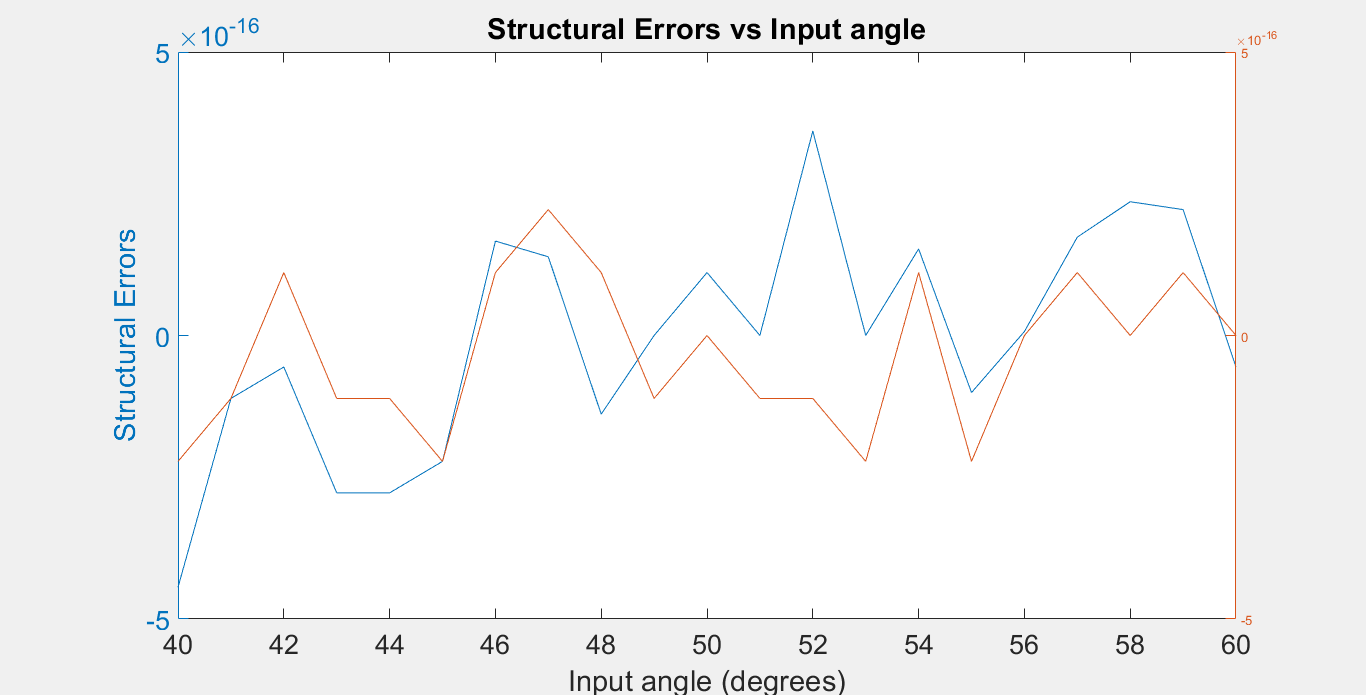

figure(2)
%plot(theta2C, sError, 'r', 'LineWidth',2)
plotyy(theta2C, sError, theta2C, sError2)
title('Structural Errors vs Input angle')
xlabel('Input angle (degrees)')
ylabel('Structural Errors')
set(gcf,'Position', get(0,'Screensize'));
set(gcf,'Visible','on')
set(gca, 'FontSize', 20)